# PRMIA Challenge Data Preparation

This script will download and save data used for the 2019 PRMIA Risk Managment Challenge. First create the data folder and then dowload data.

mkdir('Data')

## Historical New England Electricity Data

Daily [pricing reports](https://www.iso-ne.com/isoexpress/web/reports/pricing/-/tree/zone-info) from the New England ISO website will need to be downloaded manually and saved to the *Data* folder.  The files to download:

- 2018 SMD Hourly Data [XLSX](https://www.iso-ne.com/static-assets/documents/2018/02/2018_smd_hourly.xlsx)

- 2017 SMD Hourly Data [XLSX](https://www.iso-ne.com/static-assets/documents/2017/02/2017_smd_hourly.xlsx)

- 2016 SMD Hourly Data [XLS](https://www.iso-ne.com/static-assets/documents/2016/02/2016_smd_hourly.xls) (rename to 2016_smd_hourly.xls)

- 2015 SMD Hourly Data [XLS](https://www.iso-ne.com/static-assets/documents/2015/02/smd_hourly.xls) (rename to 2015_smd_hourly.xls)

- 2014 SMD Hourly Data [XLS](https://www.iso-ne.com/static-assets/documents/2015/02/smd_hourly.xls)

- 2013 SMD Hourly Data [XLS](https://www.iso-ne.com/static-assets/documents/markets/hstdata/znl_info/hourly/2013_smd_hourly.xls)

- 2012 SMD Hourly Data [XLS](https://www.iso-ne.com/static-assets/documents/markets/hstdata/znl_info/hourly/2012_smd_hourly.xls)

- 2011 SMD Hourly Data [XLS](https://www.iso-ne.com/static-assets/documents/markets/hstdata/znl_info/hourly/2011_smd_hourly.xls)

clearvars
% files downloaded manually and saved to Data folder
files = dir('Data\*_smd_hourly*');
assert(~isempty(files),'No electicity data found, please download and add to the Data directory')
xlsfiles = fullfile(files(1).folder, {files.name});

% the spreadsheets change the number and name of the variables, so defind
% common names
varNames = {'Date','Hr_End','DA_Demand','RT_Demand','DA_LMP','DA_EC'...
    'DA_CC', 'DA_MLC','RT_LMP','RT_EC','RT_CC','RT_MLC','Dry_Bulb',...
    'Dew_Point','System_Load','Reg_Service_Price','Reg_Capacity_Price'};

% create empty data arrays and keep variable names the same
elecPrices = timetable();
for f= 1:length(xlsfiles)
    try
        T = readtable(xlsfiles{f},'Sheet','ISONE CA');
        T.Properties.VariableNames = varNames([1:end-2,end]);
        T.(varNames{end-1}) = NaN(height(T),1);
    catch
        T = readtable(xlsfiles{f},'Sheet','ISO NE CA');
        T = T(:,varNames);
        % ensure hours are numbers
        if iscellstr(T.Hr_End)
            T.Hr_End = double(string(T.Hr_End));
        end
    end
    disp(['Processing: ',xlsfiles{f}])
    
    % convert the Date and Hour into a datetime
    T.Date = T.Date + hours(T.Hr_End-1);
    
    % synchronize the price data
    elecPrices = [elecPrices; T];
end

Processing: C:\MATLAB\PRMIACaseStudy2019\Data\2011_smd_hourly.xls
Processing: C:\MATLAB\PRMIACaseStudy2019\Data\2012_smd_hourly.xls
Processing: C:\MATLAB\PRMIACaseStudy2019\Data\2013_smd_hourly.xls
Processing: C:\MATLAB\PRMIACaseStudy2019\Data\2014_smd_hourly.xls
Processing: C:\MATLAB\PRMIACaseStudy2019\Data\2015_smd_hourly.xls
Processing: C:\MATLAB\PRMIACaseStudy2019\Data\2016_smd_hourly.xls
Processing: C:\MATLAB\PRMIACaseStudy2019\Data\2017_smd_hourly.xlsx
Processing: C:\MATLAB\PRMIACaseStudy2019\Data\2018_smd_hourly.xlsx


elecPrices = table2timetable(elecPrices);

Save the electicity data

save Data\elecPrices.mat elecPrices

## Natural Gas Spot and Future Prices

Daily pricing data for natural gas can be downloaded from U.S. Energy Information Administration.  Links to the webistes describing the data sets are provided below.

- [Natural Gas Spot Prices](https://www.eia.gov/dnav/ng/hist/rngwhhdD.htm)

- [Natural Gas Futures Contract 1](https://www.eia.gov/dnav/ng/hist/rngc1d.htm)

- [Natural Gas Futures Contract 2](https://www.eia.gov/dnav/ng/hist/rngc2d.htm)

- [Natural Gas Futures Contract 3](https://www.eia.gov/dnav/ng/hist/rngc3d.htm)

- [Natural Gas Futures Contract 4](https://www.eia.gov/dnav/ng/hist/rngc4d.htm)

Now use [`websave`](matlab:doc websave) to fetch the raw spreadsheet files for the spot and futures prices and save them in the *Data* folder while creating a MATLAB [`timetable`](matlab:doc timetable) of the natural gas prices of interest`. `[`fullfile`](matlab:doc fullfile) is used to create a platform independient path to the *Data* folder and [readtable](matlab:doc readtable) imports the data from the 'Data 1' tab in the downloaded spreadsheet. 

clearvars
% Source urls and spreadsheet files to download
baseurl = 'https://www.eia.gov/dnav/ng/hist_xls/';
ngsrc = {'RNGWHHDd.xls', 'RNGC1d.xls', 'RNGC2d.xls', 'RNGC3d.xls', 'RNGC4d.xls'};

% create empty data arrays
ngPrices = timetable();
xlsfiles = cell(size(ngsrc));

% download the files
for f= 1:length(ngsrc)
    xlsfiles{f} = websave( fullfile('Data', ngsrc{f}), [baseurl,ngsrc{f}] );
    disp(['Data saved: ', xlsfiles{f}]);
    
    % extract the variable name from the downloaded file and create a table
    [~, varName ] = fileparts(xlsfiles{f});
    opts = detectImportOptions(xlsfiles{f},'Sheet','Data 1');
    T = readtable(xlsfiles{f},opts);
    T.Properties.VariableNames = {'Date', varName};
    
    % syncronize the price data
    ngPrices = synchronize(ngPrices, table2timetable(T));
end

Data saved: C:\MATLAB\PRMIACaseStudy2019\Data\RNGWHHDd.xls
Data saved: C:\MATLAB\PRMIACaseStudy2019\Data\RNGC1d.xls
Data saved: C:\MATLAB\PRMIACaseStudy2019\Data\RNGC2d.xls
Data saved: C:\MATLAB\PRMIACaseStudy2019\Data\RNGC3d.xls
Data saved: C:\MATLAB\PRMIACaseStudy2019\Data\RNGC4d.xls


Peak into the data for the last (most recent) set of data

tail(ngPrices)

ans = 8×5 timetable
            Time            RNGWHHDd    RNGC1d    RNGC2d    RNGC3d    RNGC4d
    ____________________    ________    ______    ______    ______    ______

    04-Jan-2019 00:00:00       2.8      3.044     2.905     2.688      2.66 
    07-Jan-2019 00:00:00      2.74      2.944     2.847     2.677     2.662 
    08-Jan-2019 00:00:00      2.89      2.967     2.835     2.695     2.683 
    09-Jan-2019 00:00:00      2.92      2.984      2.84     2.706     2.696 
    10-Jan-2019 00:00:00      2.95      2.969     2.813     2.706     2.698 
    11-Jan-2019 00:00:00      2.95      3.099     2.945     2.769     2.747 
    14-Jan-2019 00:00:00      3.36      

and create a plot to visually check the data was downloaded correctly.

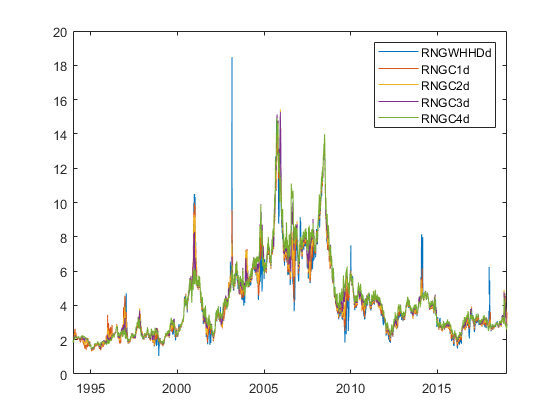

plot(ngPrices.Time,ngPrices.Variables)
legend(ngPrices.Properties.VariableNames)

Save the natural gas data for later use in the current working directory.

save Data\ngPrices.mat ngPrices